# Load Cell Parsing

## Import Data

clear; clc; close all;
filename = 'load_cell_test_data.csv';
opts = detectImportOptions(filename);
data = readtable(filename, opts);

## Format Data

raw_time = data.Timestamp; % e.g., 13025702930
force_data = data.Fz;   % The load cell reading
time = (raw_time - raw_time(1)) ./ 1e6;
force = -1.*force_data;
force = force - force(1);

## Search for Peaks

minHeight = 5; %Newtons
nominal_sample_fq = 1000; % 1,000 Hz
minPeakDistance = 1.*nominal_sample_fq; % seconds
[pks, locs] = findpeaks(force, 'MinPeakHeight', minHeight, 'MinPeakDistance', minPeakDistance);
peak_times = time(locs);

confirmation_array = [2 3 5 7 8]; %manual input; set as length of array when unknown
%confirmation_array = 1:length(pks); %default
confirmed_peaks = pks(confirmation_array);
confirmed_peak_times = peak_times(confirmation_array);

% Display peaks
fprintf('Found %d peaks in the dataset.\n', length(pks));

Found 8 peaks in the dataset.


confirmed_peak_table = table(confirmed_peak_times, confirmed_peaks, 'VariableNames', {'Time_s', 'Force_Value'});
disp(confirmed_peak_table);

    Time_s    Force_Value
    ______    ___________

    15.622       9.226   
     21.31      5.4342   
    25.092      7.0179   
    29.152      10.525   
    33.375      7.5427   



## Graph Peaks

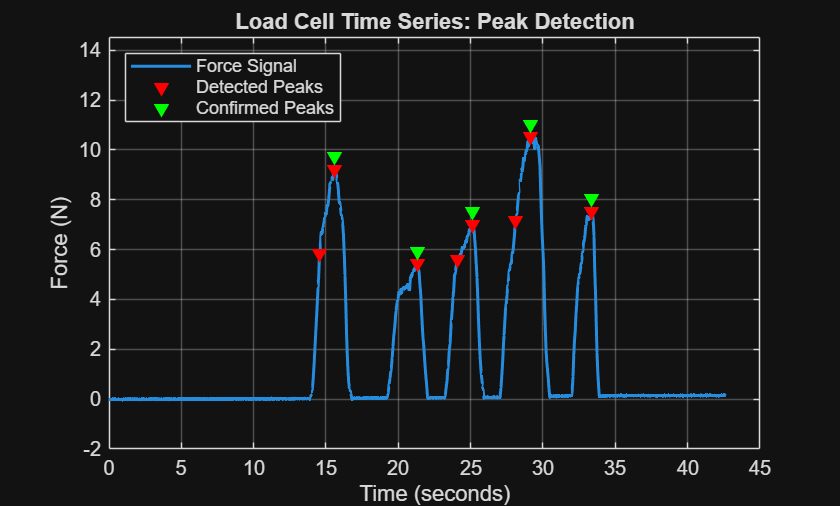

plot(time, force, 'LineWidth', 1.5);
hold on;
plot(peak_times, pks, 'rv', 'MarkerFaceColor', 'r'); % Red triangles at peaks
plot(confirmed_peak_times, confirmed_peaks + 0.5, 'gv', 'MarkerFaceColor', 'g'); % Red triangles at peaks
grid on;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-2 max(force)+4]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Detected Peaks', 'Confirmed Peaks', 'Location', 'northwest');